clc,clear
% matlab中，不存在的边设置成0
% 6个顶点，初始化定义6x6的全零矩阵作为邻接矩阵
a = zeros(6);

% 注意，最小生成树是针对无向图的，每条边权重只需要设一次。1到2和2到1是同一条边
% 因此，可仅使用邻接矩阵的上三角矩阵来构造图G
a(1,[2 3])=[14 18];       % 顶点1到其他顶点的边的权重
a(2,[3:5])=[13 18 16];   % 顶点2到顶点3、顶点9的边的权重
a(3,[4 5])=[12 16];       % 同上。因为写过1到3，和2到3的边的权重，无需重复设
a(4,[5 6])=[14 19];       
a(5,6)=10;

% graph在图论课程中讲过
s=cellstr(strcat('城市',int2str([1:6]')));
G=graph(a,s,'upper');  % 仅使用 A 的上三角矩阵来构造图G。
p=plot(G,'EdgeLabel',G.Edges.Weight);   % 绘制出图G

% minspantree函数求解最小生成树
% T=minspantree(G)是默认使用Prim算法
T=minspantree(G,'Method','sparse');      % 可指定使用Kruskal算法

L = sum(T.Edges.Weight)     % 对最小生成树的边的权重求和

L = 63

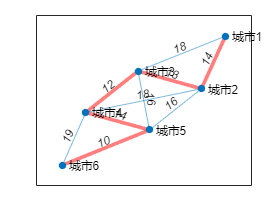

highlight(p,T,"EdgeColor","red",'LineWidth',2.5)